### Date: 

29.01.23

### Goals: 

Resonator assembly by selecting the optimal configuration of mirrors (attempt with ***teflon-air-teflon-air-teflon-air-teflon-air-teflon-air-teflon mirrors***) second repetition!

### Equipment: 

Optical element circuit([Shown in this file](matlab:open('./Circuit&Synthesizer_adjustment.mlx'))), synthesizer([Adjustment shown in this file](matlab:open('./Circuit&Synthesizer_adjustment.mlx'))), resonator tube, teflon mirrors (*6), air mirrors (5 single)

### Experiment: 

We assemble our resonating system by successively laying on teflon mirror (~260 µm), air mirror (single), teflon mirror (~260 µm), air mirror (single), teflon mirror (~260 µm), air mirror (single),teflon mirror (~260 µm), air mirror (single),teflon mirror (~260 µm), air mirror (single),teflon mirror (~260 µm). Then put it into resonator tube and pass through the laser beam.

### Results:

- 0 µm - maximal mirrors shift (initially)

- 0.288 µm - resonant mirrors shift (finally)

- the resulting power versus frequency is shown in the graph below

### Features:

- resonance with a very good mobility

filename = 'C:\Users\aomel\Downloads\teflonn-air (x5).h5';
h5disp(filename);

HDF5 teflonn-air (x5).h5 
Group '/' 
    Group '/FileType' 
        Attributes:
            'AgilentH5FileType':  'Agilent Waveform'
    Group '/Frame' 
        Attributes:
            'ModelNumber':  'MSO-X 4154A'
            'SerialNumber':  'MY56310590'
            'DateTime':  '29-Jan-2023 18:05:01'
            'SoftwareVersion':  '07.31.2020012900'
    Group '/Waveforms' 
        Attributes:
            'NumWaveforms':  3
        Group '/Waveforms/Channel 1' 
            Attributes:
                'WaveformType':  AVERAGE
                'Start':  0
                'NumPoints':  64516
                'NumSegments':  0
                'Count':  1
                'XDispRange':  0.500000
                'XDispOrigin':  -0.370000
                'XInc':  0.000008
                'XOrg':  -0.370312
                'XUnits':  'Second'
                'YDispRange':  0.800000
                'YDispOrigin':  -0.001250
                'YInc':  0.000013
                'YOrg':  -0.001250
  

data_CH1 = h5read(filename,'/Waveforms/Channel 1/Channel 1 Data')

data_CH1 = 64516×1 single column vector
   -0.2155
   -0.2121
   -0.2155
   -0.2121
   -0.2188
   -0.2155
   -0.2155
   -0.2088
   -0.2155
   -0.2121


data_Math = h5read(filename,'/Waveforms/Math 2/Math 2 Data')

data_Math = 64516×1 single column vector
    0.0937
    0.1004
    0.0971
    0.1004
    0.0971
    0.0937
    0.0971
    0.1038
    0.0971
    0.1004


data_Ref = h5read(filename,'/Waveforms/WfmMem 1/WfmMem 1 Data')

data_Ref = 64516×1 single column vector
   -0.3092
   -0.3125
   -0.3125
   -0.3125
   -0.3159
   -0.3092
   -0.3125
   -0.3125
   -0.3125
   -0.3125


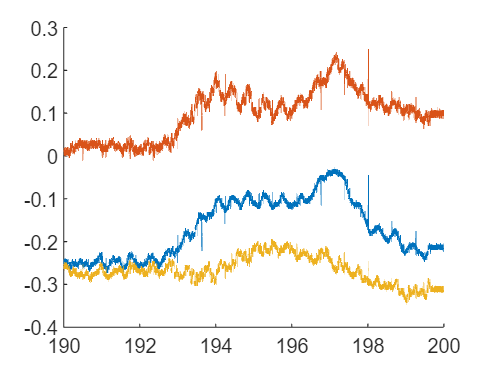

X_inc = h5readatt(filename,'/Waveforms/Math 2','XInc');
X_Axis = (0:X_inc:X_inc*(length(data_Math)-1))';
Sweep_start = 0.0519794;
Sweep_end = 0.396499;
Sweep_index = find(X_Axis > Sweep_start & X_Axis < Sweep_end);
W_start = 190; % GHz
W_end = 200; % GHz
W_inc = (W_end - W_start)/(length(Sweep_index)-1);
X_axis_freq = W_start:W_inc:W_end;
figure
hold on
plot(X_axis_freq,data_CH1(Sweep_index));
plot(X_axis_freq,data_Math(Sweep_index));
plot(X_axis_freq,data_Ref(Sweep_index));
hold off

data_to_save = [X_axis_freq',data_CH1(Sweep_index),data_Math(Sweep_index),data_Ref(Sweep_index)];
[~,fname,~]=fileparts(filename);
save([fname],'data_to_save');
